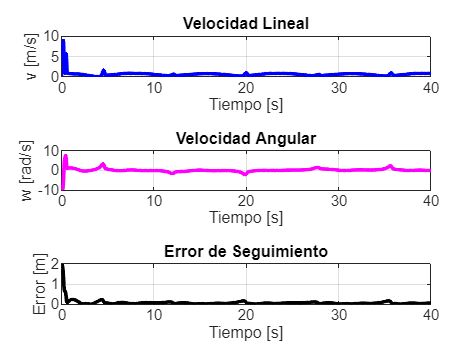

%% Trayectoria 1 - Gráficas verticales y animación
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/2;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 2*cos(0.2*t);
yd = 2*sin(0.4*t);
xd_p = -0.1*sin(0.2*t);
yd_p = 0.2*cos(0.4*t);

K = [5, 0; 0, 30];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

% Gráficas
figure('Name','Análisis de Movimiento','NumberTitle','off');
tiledlayout(3,1);  % Vertical

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

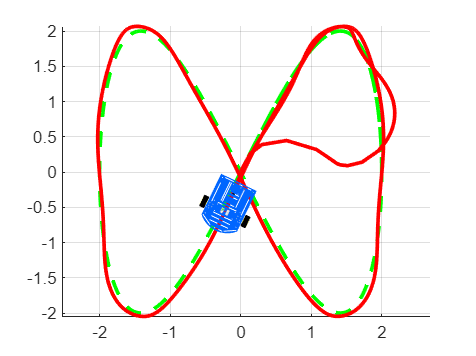


% Animación
figure('Name','Animación Trayectoria 1');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

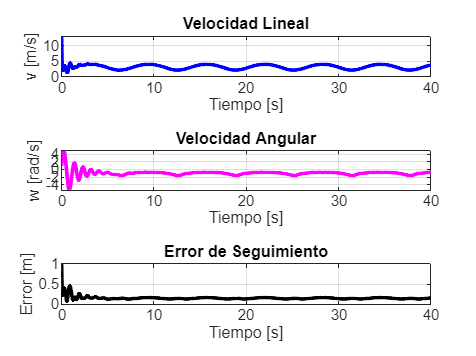

%% Trayectoria 2
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/2;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = t - 3*sin(t);
yd = 4 - 3*cos(t);
xd_p = 0.5*(1 - 3*cos(t));
yd_p = 0.5*(3*sin(t));

K = [13, 0; 0, 13];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 2');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

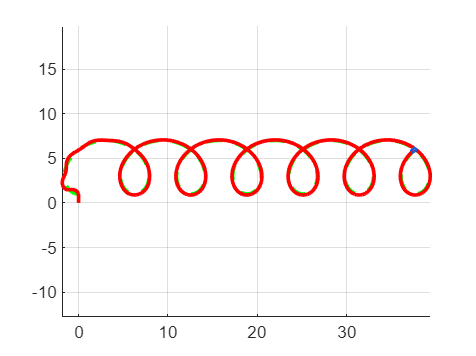


figure('Name','Animación Trayectoria 2');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

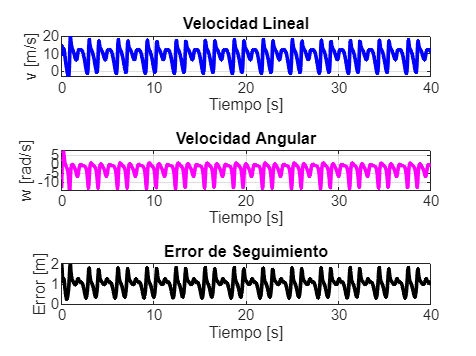

%% Trayectoria 3
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/3;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 3*cos(t) - cos(3*t);
yd = 4*sin(3*t);
xd_p = -0.1*(sin(t) - 3*sin(t));
yd_p = 0.5*(3*cos(3*t));

K = [8, 0; 0, 10];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 3');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

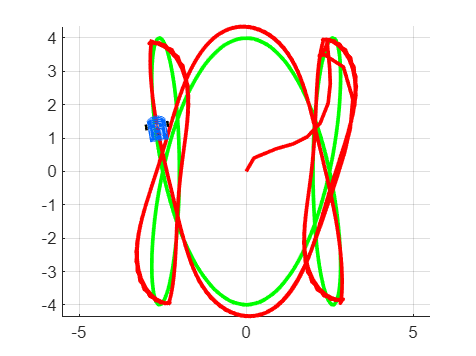


figure('Name','Animación Trayectoria 3');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

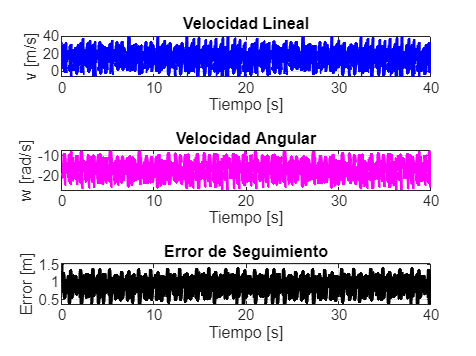

%% Trayectoria 4
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/4;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = cos(t) + 0.5*cos(7*t) + (1/3)*sin(17*t);
yd = sin(t) + 0.5*sin(7*t) + (1/3)*cos(17*t);
xd_p = -0.4*(sin(t) + 3.5*sin(7*t) - (17/3)*cos(17*t));
yd_p = 0.4*(cos(t) + 3.5*cos(7*t) - (17/3)*sin(17*t));

K = [20, 0; 0, 30];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 4');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

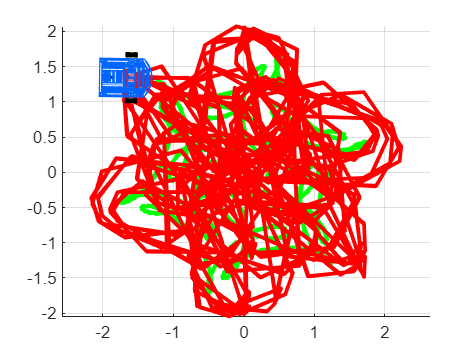


figure('Name','Animación Trayectoria 4');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

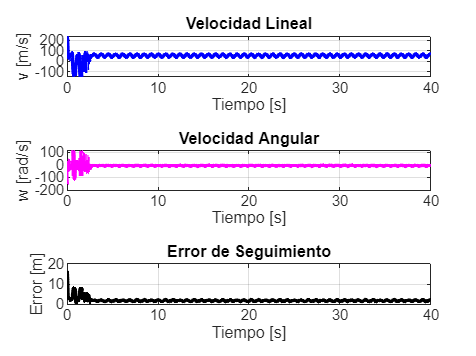

%% Trayectoria 5
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/3;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 17*cos(t) + 7*cos(17+7*t);
yd = 17*sin(t) - 7*sin(17+7*t);
xd_p = -0.5*(17*sin(t) + 49*sin(17+7*t));
yd_p = 0.5*(17*cos(t) - 49*cos(17+7*t));

K = [15, 0; 0, 17];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 5');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

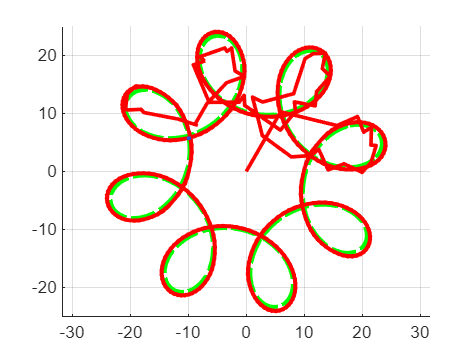


figure('Name','Animación Trayectoria 5');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

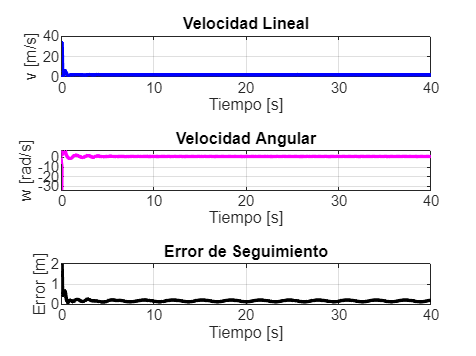

%% Trayectoria 6
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = pi/2;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 2*cos(t);
yd = 2*sin(t);
xd_p = -0.2*sin(t);
yd_p = 0.2*cos(t);

K = [17, 0; 0, 10];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 6');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

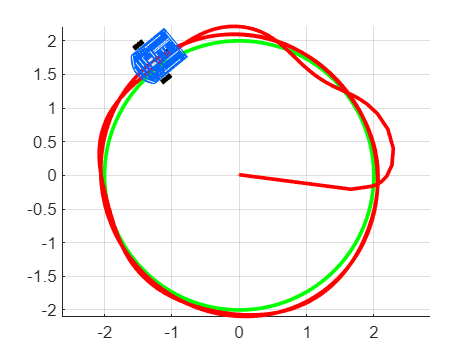


figure('Name','Animación Trayectoria 6');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

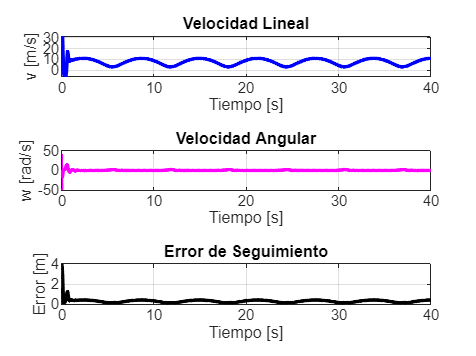

%% Trayectoria 7
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = 0;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 5*t - 4*sin(t);
yd = 5*t - 4*cos(t);
xd_p = 0.5*(5 - 4*cos(t));
yd_p = 0.5*(5 + 4*sin(t));

K = [13, 0; 0, 13];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 7');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

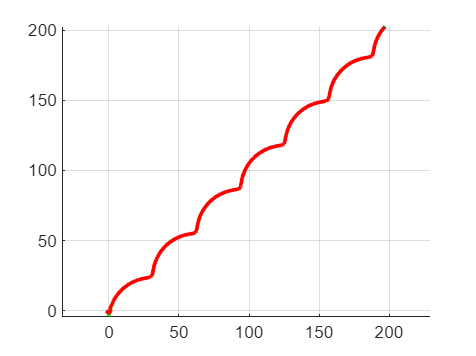


figure('Name','Animación Trayectoria 7');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

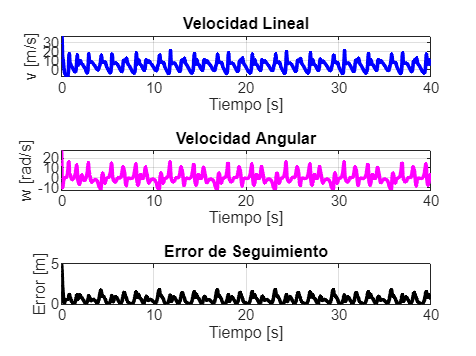

%% Trayectoria 8
close all; clc;

ts = 0.05; tf = 40;
t = 0:ts:tf; N = length(t);

x(1) = 0; y(1) = 0; theta(1) = 7*pi/4;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

xd = 4*cos(t) + cos(4*t);
yd = 4*sin(t) - sin(4*t);
xd_p = -0.2*(sin(t) + 4*sin(4*t));
yd_p = 0.2*(cos(t) - 4*cos(4*t));

K = [8, 0; 0, 20];

for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    e(k) = sqrt(ex^2 + ey^2);
    J = [cos(theta(k)) -sin(theta(k)); sin(theta(k)) cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);
    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

figure('Name','Análisis Movimiento 8');
tiledlayout(3,1)

nexttile
plot(t, v, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile
plot(t, e, 'k', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

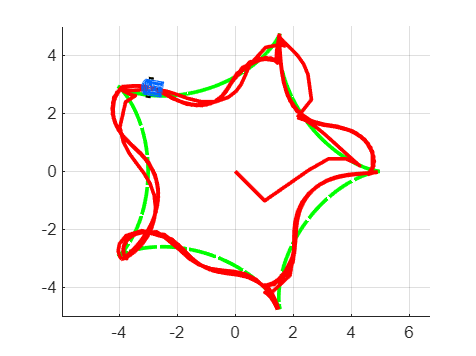


figure('Name','Animación Trayectoria 8');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end